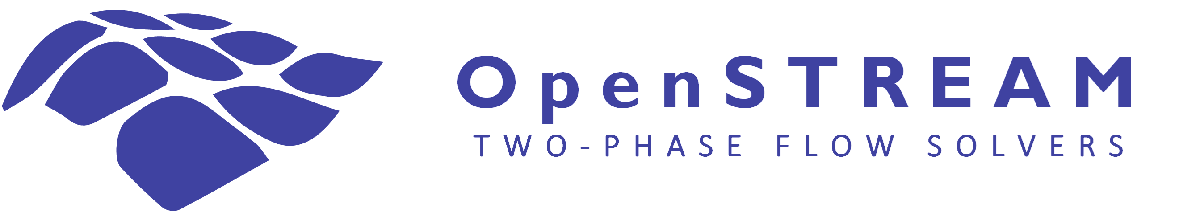

# NUTHOS-15: A Mixture Relaxation Model for Thermal Nonequilibrium in Convective Flow Boiling

Companion Live Script for:

[J.-M. Le Corre, F. Francois, and H. Anglart, “A Mixture Relaxation Model for Thermal Nonequilibrium in Convective Flow Boiling,” *15th International Topical Meeting on Nuclear Reactor Thermal-Hydraulics, Operation and Safety* (NUTHOS-15), Kashiwa-no-ha, Japan, September 28 to October 1, 2026](https://openstream.readthedocs.io/en/latest/_static/publications/LeCorre2026MRM.pdf).

This Live Script is a reproducible computational companion to the NUTHOS-15 publication. It combines explanatory text, selected experimental cases, physical-model settings, executable OpenSTREAM calculations, convergence checks, calculated-versus-measured comparisons, and interpretation in a single interactive document.

The workflow reproduces the selected OpenSTREAM calculations associated with Figures 1 to 6 of the paper. It covers two subcooled-boiling cases from the Bartolomey datasets and two post-boiling-transition cases from Becker1983. For each regime, the Mixture Relaxation Model (MRM) is compared with thermal-equilibrium and frozen-flow limiting assumptions.

The companion focuses on the calculations needed to illustrate the published figures and conclusions. It does not include all model-development activities, calibration studies, sensitivity analyses, numerical investigations, or unsuccessful model variants performed during the underlying research.

**Scope and paper mapping**

- Figures 1 and 2 show heat-flux partitioning, vapor quantities, measured void fraction, and interfacial-condensation relaxation time for the two subcooled-boiling cases.

- Figure 3 compares MRM void-fraction predictions with thermal-equilibrium and frozen-flow limits.

- Figures 4 and 5 show vapor quantities, phase and wall temperatures, measured wall temperature, and interfacial relaxation times for the two post-boiling-transition cases.

- Figure 6 compares MRM wall-temperature predictions with the two limiting models.

*Note: This file is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor.*

## 1. Setup

The relative paths assume execution from openstream-database/projects. All numerical inputs use SI units, with temperatures stored in kelvin. Generated input and session files are overwritten for reproducible reruns, while solver objects are retained in memory rather than saved to MAT-files.

% Clear the existing workspace and close open figures.
clearvars
close all

% Add OpenSTREAM-database and OpenSTREAM to the MATLAB search path.
addpath('..')
addpath(fullfile('..','..','openstream'))

% Define common file-generation and solver-output options.
inputSetOpts = {'overwriteSessionFiles',true,'LOGMODE','BOTH'};
saveResultsToFile = false;

## 2. Subcooled boiling

The subcooled-boiling evaluation uses two uniformly heated water-flow cases reported by Bartolomey. The first case has a 1.5 m heated length. The second has a 1.0 m heated section followed by a 0.4 m adiabatic section, allowing the calculated condensation and return toward equilibrium to be assessed downstream of heating. These as representative high-pressure cases from the RELAP5/MOD3 validation database.

### 2.1 Selected cases and model configuration

The selected records are TestID 22 and 35. The MRM uses wall heat-flux partitioning in the subcooled region, the Bestion void-fraction model, and an interfacial relaxation formulation. The calibrated vapor characteristic length is approximately 0.32 mm for the selected calculations.

% Select the two subcooled-boiling cases.
TestID = [22 35];
alldata = Bartolomey.Bartolomey();
runIndexes = find(ismember(alldata.dataset.TestID',TestID));

% Configure the common MRM model selections and numerical options.
opts = alldata.inputOptions();
opts.model.PROPERTIES   = 'PSYSTEM';
opts.model.WBOILINGN    = 1;
opts.model.WBOILINGXSUB = -0.2;
opts.model.VOID         = 'BESTION';
opts.model.THERMALNONEQ = 'MRM';
opts.model.THERMALRELAX = 'HOMOGENEOUS';
opts.options.SSCONVP    = 10;
opts.options.RELAXPM    = 0.8;
opts.options.RELAXHM    = 0.8;

% Simplified calibrated vapor characteristic-length model.
% The selected coefficients correspond to approximately 0.32 mm.
vaporLengthCoefficients = [0.1118 0.5];

### 2.2 MRM calculations and Figures 1–2

The MRM calculation resolves vapor mass and energy under thermal nonequilibrium. The figures compare calculated quantities with the reported void-fraction measurements and show the evolution of the interfacial-condensation relaxation time.

% Run the MRM calculations and confirm convergence.
for i = 1:numel(runIndexes)
    mrm1(i) = runBartolomey(Bartolomey.Bartolomey(runIndexes(i)), ...
        opts, vaporLengthCoefficients,inputSetOpts,saveResultsToFile);
end
mrm1.checkConvergence();

% Reproduce Figures 1 and 2.
for i = 1:numel(mrm1)
    plotBartolomey(mrm1(i));
end

The model captures the onset of significant void and the decay of void fraction through the adiabatic section of the second case. The calculated condensation relaxation time is initially large at low vapor content, decreases as quality and void fraction increase toward saturation, and rises again during downstream condensation in the adiabatic section.

### 2.3 Limiting-model comparison and Figure 3

The same cases are recalculated using two limiting assumptions. The thermal-equilibrium model represents vanishing relaxation time, while the frozen-flow model uses a very large vapor characteristic length to suppress interfacial relaxation.

% Run the thermal-equilibrium limiting model.
optsEquilibrium = opts;
optsEquilibrium.model.THERMALNONEQ = 'EQUILIBRIUM';
for i = 1:numel(runIndexes)
    mem1(i) = runBartolomey(Bartolomey.Bartolomey(runIndexes(i)), ...
        optsEquilibrium,vaporLengthCoefficients,inputSetOpts,saveResultsToFile);
end
mem1.checkConvergence();

% Run the frozen-flow limiting model.
optsFrozen = opts;
frozenLengthCoefficients = [1.0e6 0.0];
for i = 1:numel(runIndexes)
    frozen1(i) = runBartolomey(Bartolomey.Bartolomey(runIndexes(i)), ...
        optsFrozen,frozenLengthCoefficients,inputSetOpts,saveResultsToFile);
end
frozen1.checkConvergence();

% Reproduce Figure 3.
figure('Name','Subcooled boiling: model comparison', ...
    'Units','normalized','Position',[0.08 0.20 0.84 0.50]);
tiledlayout(1,numel(runIndexes),'TileSpacing','compact','Padding','compact')
for i = 1:numel(runIndexes)
    plotModelsVF(mrm1(i),mem1(i),frozen1(i));
end

The paper concludes that the measured and MRM-predicted void fractions lie between the thermal-equilibrium and frozen-flow limits for both selected cases.

## 3. Post-boiling transition

The post-boiling-transition evaluation uses two uniformly heated Becker1983 cases at 7 MPa. The cases represent film dryout followed by dispersed-film-flow boiling, with wall-temperature measurements available downstream of the measured boiling-transition elevation.

### 3.1 Selected cases and model configuration

The selected records are TestID 262 and 277. The boiling-transition elevation is imposed from each dataset record to isolate the post-transition heat-transfer calculation. The MRM uses a homogeneous void-fraction model, directs wall heat transfer to the vapor downstream of transition, and calculates interfacial evaporation using a calibrated effective droplet diameter of 0.15 mm at dryout.

% Select the two post-boiling-transition cases used in the paper.
TestID = [262 277];
alldata = Becker1983.Becker1983();
runIndexes = find(ismember(alldata.dataset.TestID',TestID));

% Configure the common MRM model selections and numerical options.
opts = alldata.inputOptions();
opts.model.PROPERTIES    = 'PSYSTEM';
opts.model.WBOILINGN     = 1;
opts.model.WBOILINGXSUB  = -0.2;
opts.model.VOID          = 'HOMOGENEOUS';
opts.model.THERMALNONEQ  = 'MRM';
opts.model.THERMALRELAX  = 'HOMOGENEOUS';
opts.model.RELAXCONDCOEF = [0.5e-3 1/3 1.0e-4 0.0];
opts.model.CBT            = 'ELEVATION';
opts.model.BTHTM          = 'VAPOR';
opts.options.SSCONVP    = 10;
opts.options.RELAXPM    = 0.8;
opts.options.RELAXHM    = 0.8;

% Effective liquid-droplet characteristic length at dryout [m].
dropletLengthAtDryout = 0.15e-3;

### 3.2 MRM calculations and Figures 4–5

The MRM calculations resolve vapor superheat, interfacial evaporation, and the resulting wall temperature through the post-boiling-transition region. The plotted measured values remain direct experimental wall-temperature data, while the vapor and relaxation quantities are OpenSTREAM calculations.

% Run the MRM calculations and confirm convergence.
for i = 1:numel(runIndexes)
    mrm2(i) = runBecker(Becker1983.Becker1983(runIndexes(i)), ...
        opts,dropletLengthAtDryout,inputSetOpts,saveResultsToFile);
end
mrm2.checkConvergence();

%Reproduce Figures 4 and 5.
for i = 1:numel(mrm2)
    plotBecker1983(mrm2(i));
end

The MRM captures the sharp wall-temperature rise immediately downstream of the imposed boiling transition and the downstream stable-film-boiling behavior. For the higher-mass-flux case, the measured trend inversion is not fully reproduced, indicating underestimated interfacial evaporation.

### 3.3 Limiting-model comparison and Figure 6

The post-boiling-transition cases are recalculated using thermal-equilibrium and frozen-flow limits. The frozen calculation uses a very large droplet characteristic length to suppress interfacial evaporation.

% Run the thermal-equilibrium limiting model.
optsEquilibrium = opts;
optsEquilibrium.model.THERMALNONEQ = 'EQUILIBRIUM';
for i = 1:numel(runIndexes)
    mem2(i) = runBecker(Becker1983.Becker1983(runIndexes(i)), ...
        optsEquilibrium,0.0,inputSetOpts,saveResultsToFile);
end
mem2.checkConvergence();

% Run the frozen-flow limiting model.
optsFrozen = opts;
frozenDropletLength = 1.0e6;
for i = 1:numel(runIndexes)
    frozen2(i) = runBecker(Becker1983.Becker1983(runIndexes(i)), ...
        optsFrozen,frozenDropletLength,inputSetOpts,saveResultsToFile);
end
frozen2.checkConvergence();

% Reproduce Figure 6.
figure('Name','Post-boiling transition: model comparison', ...
    'Units','normalized','Position',[0.08 0.20 0.84 0.50]);
tiledlayout(1,numel(runIndexes),'TileSpacing','compact','Padding','compact')
for i = 1:numel(runIndexes)
    plotModelsTWALL(mrm2(i),mem2(i),frozen2(i));
end

The MRM and measured wall temperatures generally lie between the thermal-equilibrium and frozen-flow limits. A local exception occurs immediately downstream of the boiling transition in the second case, suggesting that the vapor wall heat-transfer treatment requires further investigation.

## 4. Summary of reproduced findings

The subcooled-boiling calculations show that the MRM predicts the development and downstream interfacial condensation of vapor using a relaxation formulation rather than an algebraic subcooled-boiling quality correlation. The post-boiling-transition calculations show that the same framework predicts the development and downstream interfacial evaporation of liquid. The most relevant calculated parameters are void fraction and  vapor superheating / wall temperature, respectively. In both regimes, the results are compared with thermal-equilibrium and frozen-flow limits and reproduce the principal trends discussed in the NUTHOS-15 paper.

The selected characteristic lengths are calibrated effective scales and should not be interpreted directly as measured bubble or droplet diameters. The companion demonstrates the published model configuration and selected results; it does not establish general validation outside the investigated conditions.

## 5. Local calculation and plotting functions

function bartolomey = runBartolomey(bartolomey,opts,coefficients,inputSetOpts,saveResultsToFile)
% RUNBARTOLOMEY Configure and run one subcooled-boiling case.

entryData = bartolomey.entryData;
cp = CoolPropWrapper.CoolPropWrapper('water');

% Calculate the effective vapor characteristic length.
pressure = entryData.Pressure;
massFlux = entryData.MassFlux;
viscosity = cp.viscosity('P',pressure,'Q',0);
reynoldsNumber = massFlux*entryData.Diameter/viscosity;
diameter = coefficients(1)/reynoldsNumber.^coefficients(2);

localOpts = opts;
localOpts.model.RELAXCONDCOEF = [diameter 1/3 1.0e-4 0.0];
bartolomey.makeInputFiles(inputOptions=localOpts, ioDirectory="NUTHOS15_MRM/Bartolomey");

% Preserve and restore the current warning configuration.
warningState = warning;
warningCleanup = onCleanup(@()warning(warningState));
warning('off','all')
bartolomey.runCase('Mixture','inputSetOpts',inputSetOpts,'saveResultsToFile',saveResultsToFile);
clear warningCleanup
end

function becker = runBecker(becker,opts,dropletLength,inputSetOpts,saveResultsToFile)
% RUNBECKER Configure and run one post-boiling-transition case.

localOpts = opts;
localOpts.model.RELAXEVAPCOEF = [dropletLength 1/3 1.0e-5 0.0];
localOpts.model.CBTELEVATION = becker.entryData.ZBO;
becker.makeInputFiles(inputOptions=localOpts, ioDirectory="NUTHOS15_MRM/Becker");

% Preserve and restore the current warning configuration.
warningState = warning;
warningCleanup = onCleanup(@()warning(warningState));
warning('off','all')
becker.runCase('Mixture','inputSetOpts',inputSetOpts,'saveResultsToFile',saveResultsToFile);
clear warningCleanup
end

function plotBartolomey(bartolomey)
% PLOTBARTOLOMEY Reproduce a detailed subcooled-boiling figure.

bartolomey.results.plotz('display',{'HFLUX','VR','TRELAX'},'arrangement','horizontal','resize',1.1);

entryData = bartolomey.entryData;
if isstring(entryData.Elevation)
    mixture = bartolomey.results.mixture;
    elevation = interp1(mixture.XEQ,mixture.Z,entryData.Quality);
else
    elevation = entryData.Elevation;
end

ax(1) = nexttile(1);
xlim(ax(1),[0 1.5])
if numel(ax(1).Children) >= 4
    delete(ax(1).Children(4))
end

ax(2) = nexttile(2);
ax(2).Children(1).LineWidth = 2;
hold(ax(2),'on')
plot(ax(2),elevation,entryData.VoidFraction,'k*','DisplayName','Void fraction (measured)');
xlim(ax(2),[0 1.5]); ylim(ax(2),[-0.2 0.7]);

ax(3) = nexttile(3);
xlim(ax(3),[0 1.5]); ylim(ax(3),[0 1]); legend(ax(3),'off');
if numel(ax(3).Children) >= 2
    delete(ax(3).Children(2));
end
lines = findobj(ax(3),'Type','Line');
if ~isempty(lines)
    lines(1).XData = lines(1).XData(2:end);
    lines(1).YData = lines(1).YData(2:end);
end
end

function plotBecker1983(becker)
% PLOTBECKER1983 Reproduce a detailed post-transition figure.

becker.results.plotz('display',{'T','VR','TRELAX'},'arrangement','horizontal','resize',1.1,'unitTemp','C');

entryData = becker.entryData;
elevation = entryData.Elevation;
wallTemperature = entryData.WallTemperature - 273.15;

ax(1) = nexttile(1); ylim(ax(1),[-0.1 1.2]);
ax(2) = nexttile(2); hold(ax(2),'on');
if numel(ax(2).Children) >= 2
    ax(2).Children(2).LineWidth = 2;
end
if ~isempty(ax(2).Children)
    delete(ax(2).Children(end));
end
if ~isempty(ax(2).Children)
    delete(ax(2).Children(1));
end
plot(ax(2),elevation,wallTemperature,'k*','DisplayName','Wall (measured)');
ylim(ax(2),[270 665]);

ax(3) = nexttile(3); ylim(ax(3),[0 1]);
lines = findobj(ax(3),'Type','Line');
if ~isempty(lines)
    lines(1).XData = lines(1).XData(2:end);
    lines(1).YData = lines(1).YData(2:end);
end
if numel(lines) >= 2
    index = becker.results.mixture.CBTIDX - 1;
    lines(2).XData = lines(2).XData(index:end);
    lines(2).YData = lines(2).YData(index:end);
end
end

function plotModelsVF(mrm,equilibrium,frozen)
% PLOTMODELSVF Compare void fraction with the limiting models.

nexttile; hold on; grid on
z = equilibrium.results.Z;
plot(z,mrm.results.mixture.VF,'.-','DisplayName','Relaxation','LineWidth',2)
plot(z,equilibrium.results.mixture.VF,'.--','DisplayName','Equilibrium')
plot(z,frozen.results.mixture.VF,'.--','DisplayName','Frozen')

entryData = mrm.entryData;
if isstring(entryData.Elevation)
    mixture = mrm.results.mixture;
    elevation = interp1(mixture.XEQ,mixture.Z,entryData.Quality);
else
    elevation = entryData.Elevation;
end
plot(elevation,entryData.VoidFraction,'k*','DisplayName','Measured')

xlabel('Axial position [m]'); ylabel('Void fraction [-]')
xlim([0 1.5]); ylim([0 0.85]); legend('Location','northwest')
set(gca,'FontSize',13)
end

function plotModelsTWALL(mrm,mem,frozen)
% PLOTMODELSTWALL Compare wall temperature with the limiting models.

nexttile; hold on; grid on
z = mem.results.Z;
plot(z,mrm.results.mixture.TWALL-273.15,'.-','DisplayName','Relaxation','LineWidth',2)
plot(z,mem.results.mixture.TWALL-273.15,'.--','DisplayName','Equilibrium')
plot(z,frozen.results.mixture.TWALL-273.15,'.--','DisplayName','Frozen')

entryData = mrm.entryData;
plot(entryData.Elevation,entryData.WallTemperature-273.15,'k*','DisplayName','Measured')

xlabel('Axial position [m]'); ylabel('Wall temperature [C]')
xlim([0 7]); ylim([270 805]); legend('Location','northwest')
set(gca,'FontSize',13)
end